# Ejercicios de optimización de funciones

## Encontrar un máximo o un mínimo local

7.3 Locate the minimum of the function 

*f *(*x*) = 3 + 6*x *+ 5*x^*2 + 3*x^*3 + 4*x^*4 

f = @(x) 3 + 6*x + 5*x.^2 + 3*x.^3 + 4*x.^4

f = function_handle with value:
    @(x)3+6*x+5*x.^2+3*x.^3+4*x.^4


min = newtonOpt(f, -1, 1)

min = -0.5867

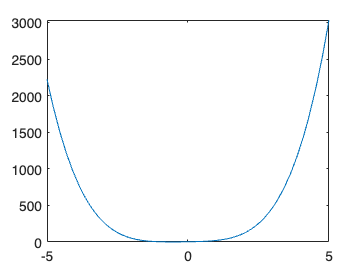

fplot(f)

7.2 Determine the maximum and the corresponding value of x for the function 

*f *(*x*) = −*x^*2 + 8*x *− 12 

f = @(x) -x.^2 + 8*x -12

f = function_handle with value:
    @(x)-x.^2+8*x-12


max = newtonOpt(@(x) -f(x), -1, 1)

max = 4

fmax = f(max)

fmax = 4

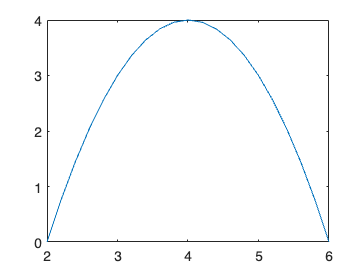

fplot(f)

7.4 Given 

*f *(*x*) = −1.5*x^*6 − 2*x^*4 + 12*x *

(a) Plot the function. 

f = @(x) -1.5*x.^6 - 2*x.^4 + 12*x

f = function_handle with value:
    @(x)-1.5*x.^6-2*x.^4+12*x


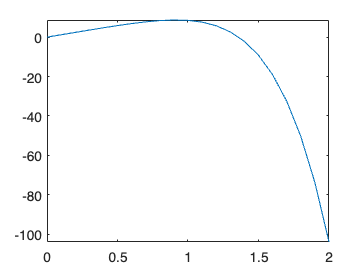

x = 0:0.1:2;
plot(x, f(x))

(b) Use analytical methods to prove that the function is con­cave for all values of *x*. 

`Si f es dos veces diferenciable, entonces f es estrictamente cóncava si y solo si f'' no es positiva:`

`Función f a derivar: `$f\left(x\right)=-1\ldotp 5x^6 -2x^4 +12x$

df = diff(sym(f)) % primera derivada

$$df = -9\,x^{5}-8\,x^{3}+12$$

ddf = diff(diff(sym(f))) % segunda derivada

$$ddf = -45\,x^{4}-24\,x^{2}$$

`Como `${f^{\prime } }^{\prime } <0\;\;\;\forall \;x\Rightarrow f$` es estrictamente cóncava.`

(c) Find the maximum *f*(*x*) and the corre­sponding value of *x*. 

max = goldenSS(@(x) -f(x), -10, 10)

max = 0.9169

fmax = f(max)

fmax = 8.6979

## Código de las funciones

Golden section search

function [x, i] = goldenSS(f, a, b)
    TOL = eps;
    MAX_ITER = 53;
    x = (a + b) / 2;
    g = (1 + sqrt(5)) / 2 - 1;
    dist = g * (b - a);

    x1 = a + dist;
    fx1 = f(x1);
    x2 = b - dist;
    fx2 = f(x2);

    i = 0;
    flag = true;
    while flag
        dist = g * dist;
        if fx1 < fx2
            a = x2;
            x2 = x1;
            fx2 = fx1;
            x1 = a + dist;
            fx1 = f(x1);
        else
            b = x1;
            x1 = x2;
            fx1 = fx2;
            x2 = b - dist;
            fx2 = f(x2);
        end
        x = (a + b) / 2;   
        i = i + 1;
        flag = abs((b - a) / x) > TOL && i < MAX_ITER;     
    end
end

Newton optimization

function [x, i, m] = newtonOpt(f, a, b)
    TOL = eps;
    MAX_ITER = 53;
    x = (a + b) / 2;
    df = diff(sym(f));
    ddf = matlabFunction(diff(df));
    df = matlabFunction(df);
     
    if nargin(ddf) == 0
        ddf = @(x) ddf();
    end
    
    i = 0;
    flag = true;
    while flag
        xp = x;
        dx = df(xp) / ddf(xp);
        x = xp - dx;
        i = i + 1;
        flag = abs((dx / x)) > TOL && i < MAX_ITER;     
    end
    m = ddf(x) > 0;
end